# EE 141: Digital Signal Processing

# Lab 6: Filter Design Using Butterworth Filters

# Lab Section: 022

# Name: Buddy Ugwumba 

# SID: 862063029

## Objective:

Design discrete-time lowpass filters using the continuous-time Butterworh filter design. Both the impulse invariance approach and the bilinear transformation approach will be explored in this lab

a) Chose some sampling period T and a high enough order N such that the continuous-time Butterworth filter with magnitude


$$|H_c \left(j\Omega \right)|=\frac{1}{\sqrt{1+{\left(\frac{\Omega }{\Omega_c }\right)}^{2N} }}$$


with $\Omega_c =\frac{0\ldotp 25\pi }{T}$ satisfies

- $0\ldotp 98\le |H_c \left(j\Omega \right)|\le 1$ for all $-\frac{0\ldotp 25\pi }{T}\le \Omega \le \frac{0\ldotp 25\pi }{T}$

- $\left|H_c \left(j\Omega \right)\right|\le 0\ldotp 02$ for all $-\frac{\pi }{T}\le \Omega \le \frac{0\ldotp 3\pi }{T}$ and $\frac{0\ldotp 3\pi }{T}\le \Omega \le \frac{\pi }{T}$

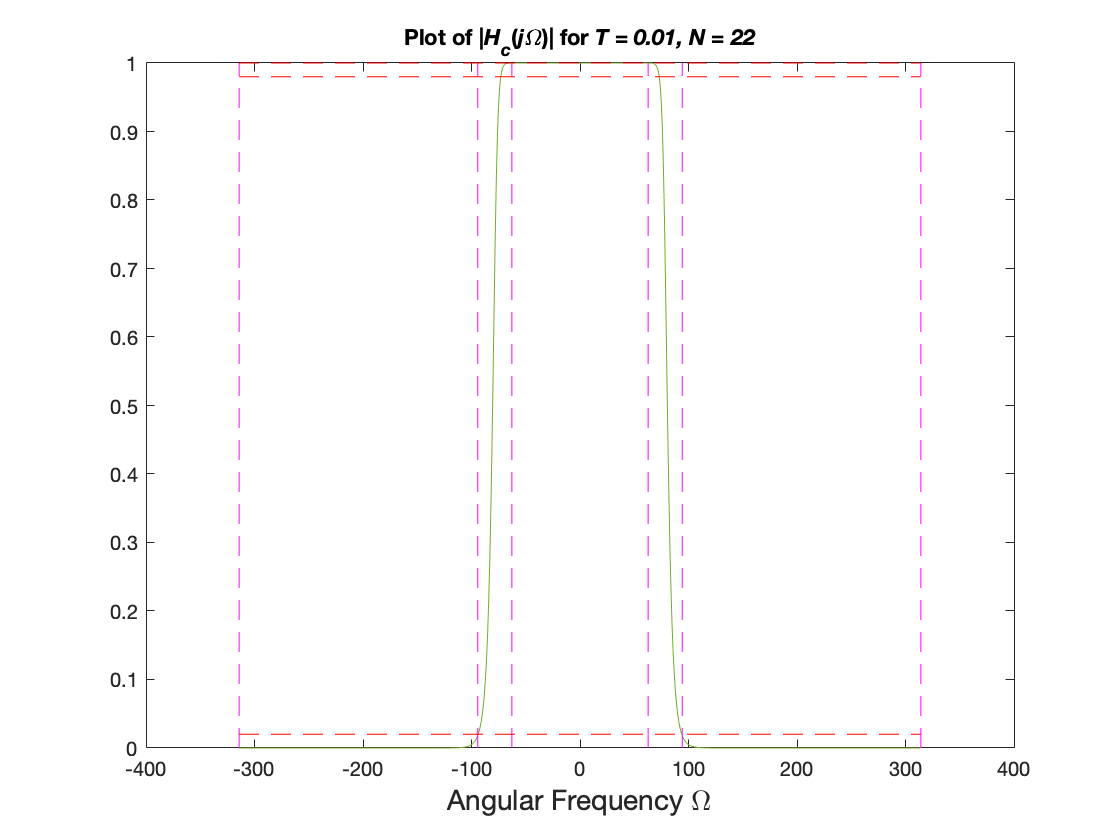

clear all close all clc
N = 22;
T =0.01;
omegaC = 0.25*pi/T;
omega = -pi/T:pi/T;

h = 1./sqrt(1+(omega./omegaC).^(2*N));
plot(omega,h);
hold on
y1 = get(gca, 'ylim');
plot([-0.2*pi./T -0.2*pi/T], y1, '--m')
plot([0.2*pi./T 0.2*pi/T], y1, '--m')
plot([-pi./T -pi/T], y1, '--m')
plot([-0.3*pi./T -0.3*pi/T], y1, '--m')
plot([pi./T pi/T], y1, '--m')
plot([0.3*pi./T 0.3*pi/T], y1, '--m')
yline1 = 0.98;
yline2 = 1;
yline3 = 0.02;
line([-pi/T,pi/T], [yline1, yline1], 'Color', 'red', 'LineStyle', '--')
line([-pi/T,pi/T], [yline2, yline2], 'Color', 'red', 'LineStyle', '--')
line([-pi/T,pi/T], [yline3, yline3], 'Color', 'red', 'LineStyle', '--')
title('Plot of |{\itH_c}({\itj\Omega})| for \itT = 0.01, \itN = 22')
xlabel('Angular Frequency \Omega', 'FontSize',14)

b)

clear all close all clc
N = 22;
T =0.01;
omegaC = 0.25*pi/T;
omega = -pi:0.01:pi;
NN = 1:22;
sk = omegaC*exp(j*pi*(2*NN + N-1)/(2*N));
b = poly(sk);
[Ak, ssk, k] = residue(omegaC^N, b);

c) Plot $|H_d \left(e^{j\omega } \right)|$ for $-\pi \le \omega \le \pi$ b y sufficiently sampling the frequency axis (step size of 0.01 would do) On top of your plot, draw lines indication the specifications above. Are they satisfied? Discuss why or why not?

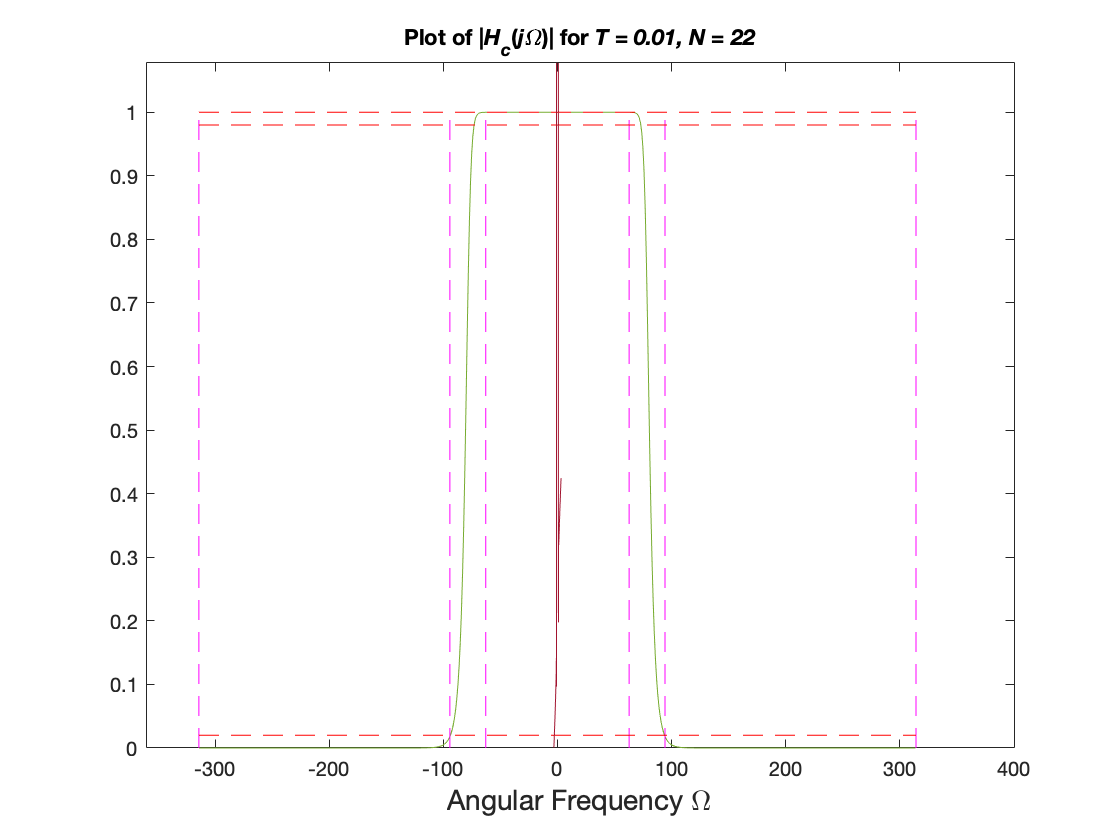

sum  = 0;
for k = 1:length(omega)
    for i = 1:22
        sum = sum + T*(Ak(i))/(1-exp(ssk(i)*T)*exp(-j*omega(k)));
    end
    Hd(k) = sum;
end

plot(omega, abs(Hd));
hold on

By checking the stop band and passband ranges, we can see from the graph the filter we designed meets our specificiations. 

2 a)

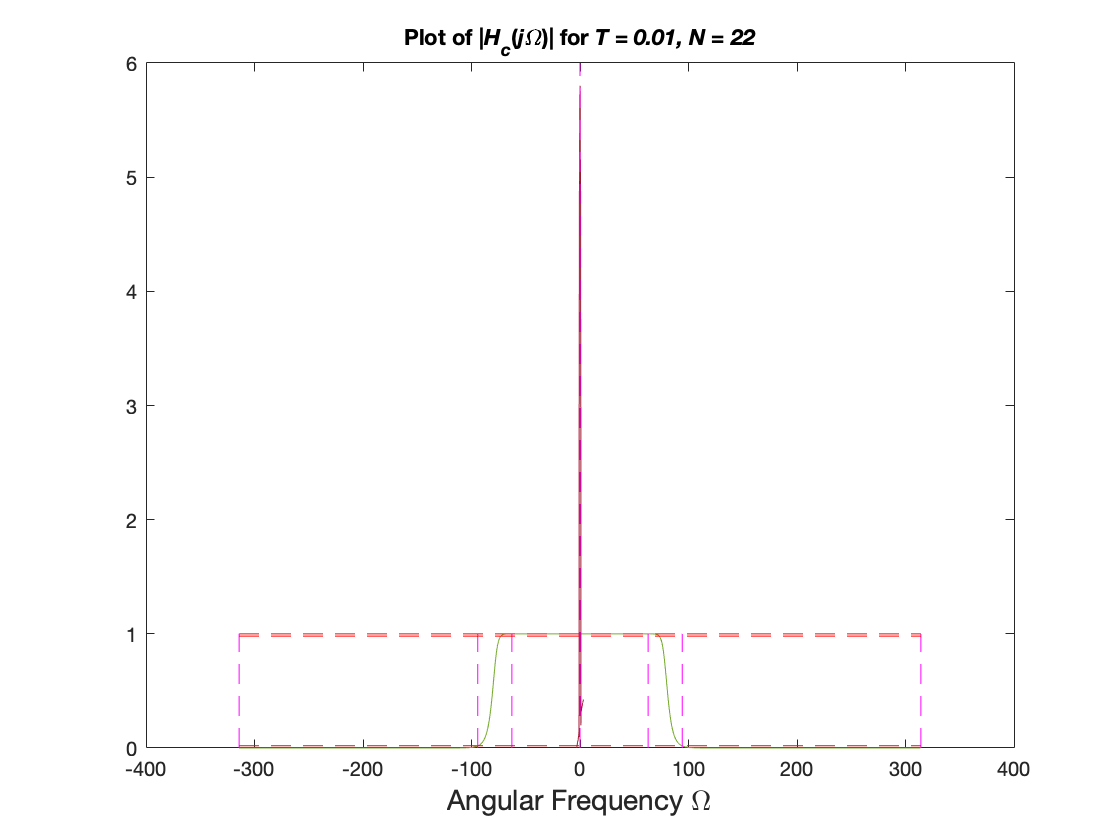

clear all close all clc
N = 22;
T =0.01;
omegaC = 0.4;
omega = tan(-pi/T):tan(pi/T);

y1 = get(gca, 'ylim');
plot([tan(-0.2*pi./T) tan(-0.2*pi/T)], y1, '--m')
plot([tan(0.2*pi./T) tan(0.2*pi/T)], y1, '--m')
plot([tan(-pi./T) tan(-pi/T)], y1, '--m')
plot([tan(-0.3*pi./T) tan(-0.3*pi/T)], y1, '--m')
plot([tan(pi./T) tan(pi/T)], y1, '--m')
plot([tan(0.3*pi./T) tan(0.3*pi/T)], y1, '--m')
title('Plot of |{\itH_c}({\itj\Omega})| for \itT = 0.01, \itN = 22')
xlabel('Angular Frequency \Omega', 'FontSize',14)

Yes, The specifications are met perfectly as shown on the graph. Using the bilinear transformation, the specifications match with the Butterworth filter designed. 